# Circular domain with target: forward simulation

Same scenario as `Circular``_d``omain`, with a **circular dielectric target** inside the Domain of Interest (DOI). This script computes and visualises the field radiated by each antenna in the presence of the target (the total field).

- square computational domain terminated in a PML (Perfectly Matched Layer), sized automatically,

- circular DOI filled with a matching medium,

- circular target inside the DOI,

- circular array of line-source antennas around the DOI.

Units are SI (m, Hz, S/m) and the time convention is $e^{+j\omega t}$.

## Setup

clc; close all; clear;
here = fileparts(mfilename('fullpath'));                       % folder of this example
if ~isfolder(fullfile(here, '..', '..', 'Forward_solvers'))      % Live Editor: use the open file
    try, here = fileparts(matlab.desktop.editor.getActiveFilename); catch, here = pwd; end
end
addpath(fullfile(here, '..', '..'));
setup_osmi;
resultsDir = fullfile(here, 'results');

## Frequency

sim.f = 1e9;                                   % Hz

## Materials


$$\varepsilon_c = \varepsilon' - j\,\frac{\sigma}{\omega\,\varepsilon_0}$$


- `background`: medium outside the DOI (also the PML medium)

- `doi`: matching medium filling the DOI

- `target`: the scatterer

materials.background.epsr  = 20;
materials.background.sigma = 0.01;             % S/m

materials.doi.epsr  = 20;
materials.doi.sigma = 0.02;

materials.target.epsr  = 60;
materials.target.sigma = 0.5;

## Geometry

Domain, DOI and antennas as in `Circular``_d``omain`, plus a circular target of radius `targetRadius` centred at `targetCenter`.

geom.doiRadius    = 0.10;
geom.antennaRing  = 0.12;
geom.nAntennas    = 24;
geom.targetRadius = 0.01;
geom.targetCenter = [0.03, 0.03];

## Mesh control


$$\lambda = \frac{c_0}{f\sqrt{\varepsilon'}}, \qquad h \approx \lambda/12$$


The target is meshed with the wavelength of the target material.

c0         = 299792458;
lambda_doi = c0/(sim.f*sqrt(materials.doi.epsr));
lambda_bg  = c0/(sim.f*sqrt(materials.background.epsr));
lambda_tgt = c0/(sim.f*sqrt(materials.target.epsr));

meshControl.hDOI    = lambda_doi/12;
meshControl.hBG     = lambda_bg/12;
meshControl.hAnt    = lambda_bg/15;
meshControl.hTarget = lambda_tgt/12;
meshControl.rAnt    = meshControl.hAnt;

## Generate the fields

One FEM solve per transmitting antenna; saved as `results/target.mat`.

opts.name      = "target";
opts.outputDir = resultsDir;
opts.current   = 1e-3;                         % A
[target, scenario] = generate_fields(sim, materials, geom, meshControl, opts);

[target] geometry radius 0.124 m -> square 0.498 m, PML from 0.187 m (0.062 m thick, gap 0.062 m)
[target] mesh: 8792 nodes, 17254 triangles; solving 24 sources ...
Saved "target"  ->  C:\Users\ibeb\OneDrive - Ciências ULisboa\Doutoramento\Coisas uteis\School_Turim\Matlab\Examples\Circular_domain_target\results\target.mat


## Geometry and mesh

The dashed red square marks the start of the PML.

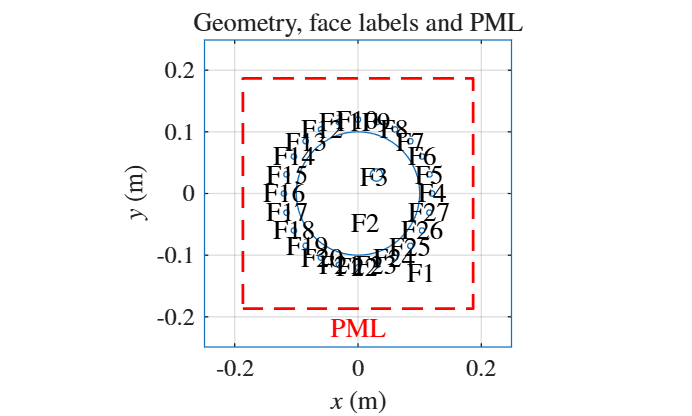

plotGeometry(scenario);

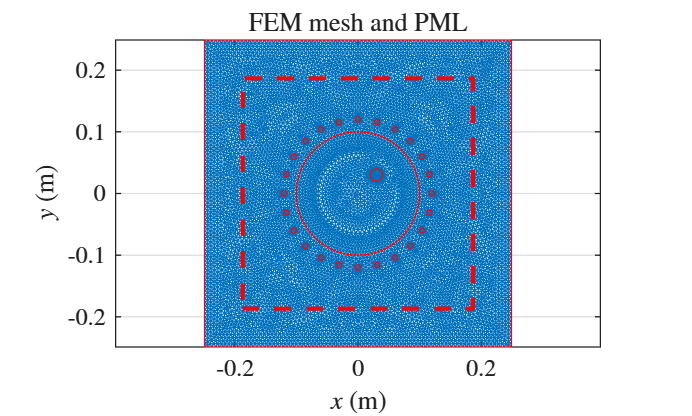

plotMesh(scenario);

## Permittivity

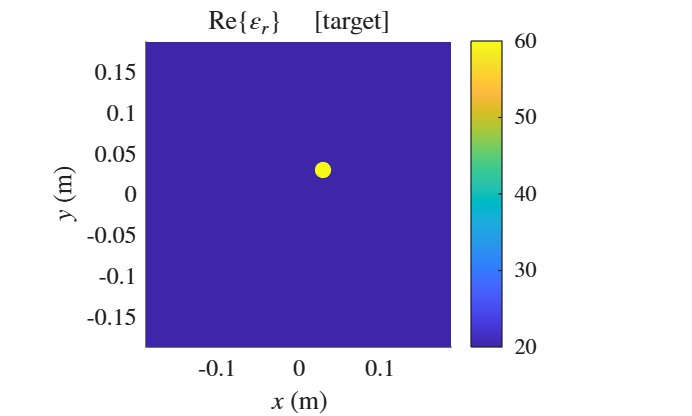

plotPermittivity(target, 'real');

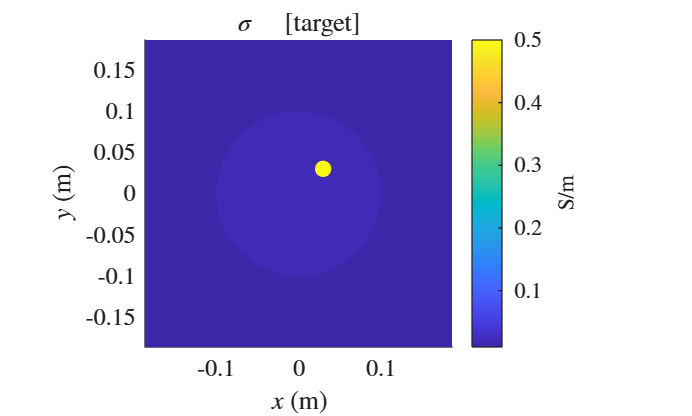

plotPermittivity(target, 'sigma');

## Field of one transmitter

Choose the transmitter `tx`. The target outline is dashed and the active antenna is marked in red.

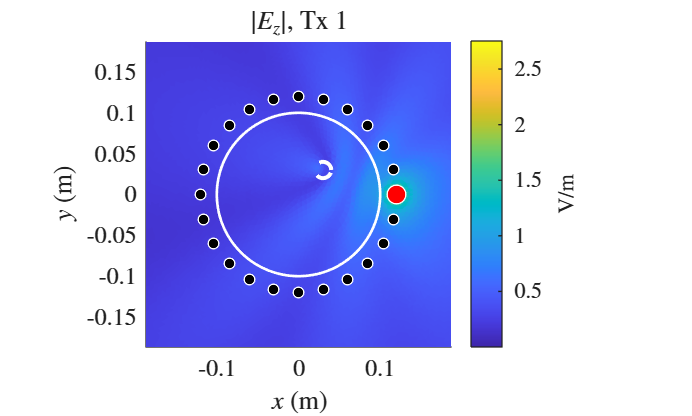

tx = 1;

plotField(target, tx, 'abs', 'Title', "$|E_z|$, Tx " + tx);

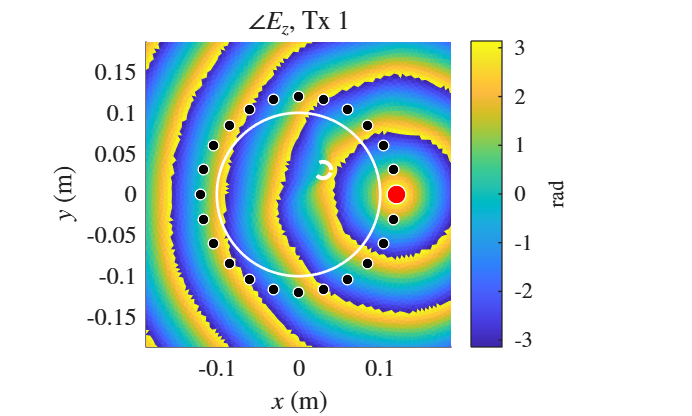

plotField(target, tx, 'phase', 'Title', "$\angle E_z$, Tx " + tx);

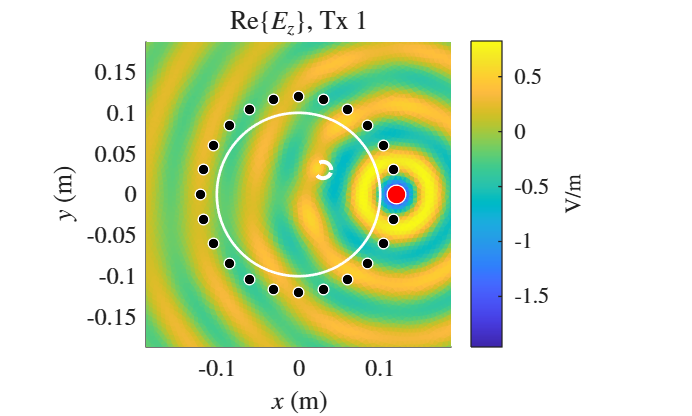

plotField(target, tx, 'real', 'Title', "$\mathrm{Re}\{E_z\}$, Tx " + tx);

## Field in dB

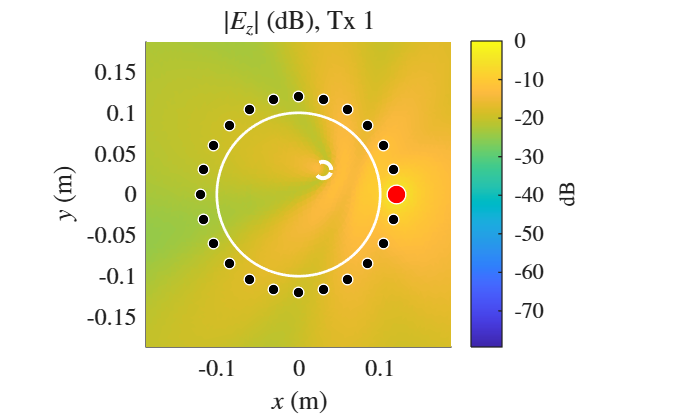

plotField(target, tx, 'dB', 'Title', "$|E_z|$ (dB), Tx " + tx);

## Interactive viewer

Colour limits are automatic; untick *Auto* in the window to type your own *Min* / *Max*.

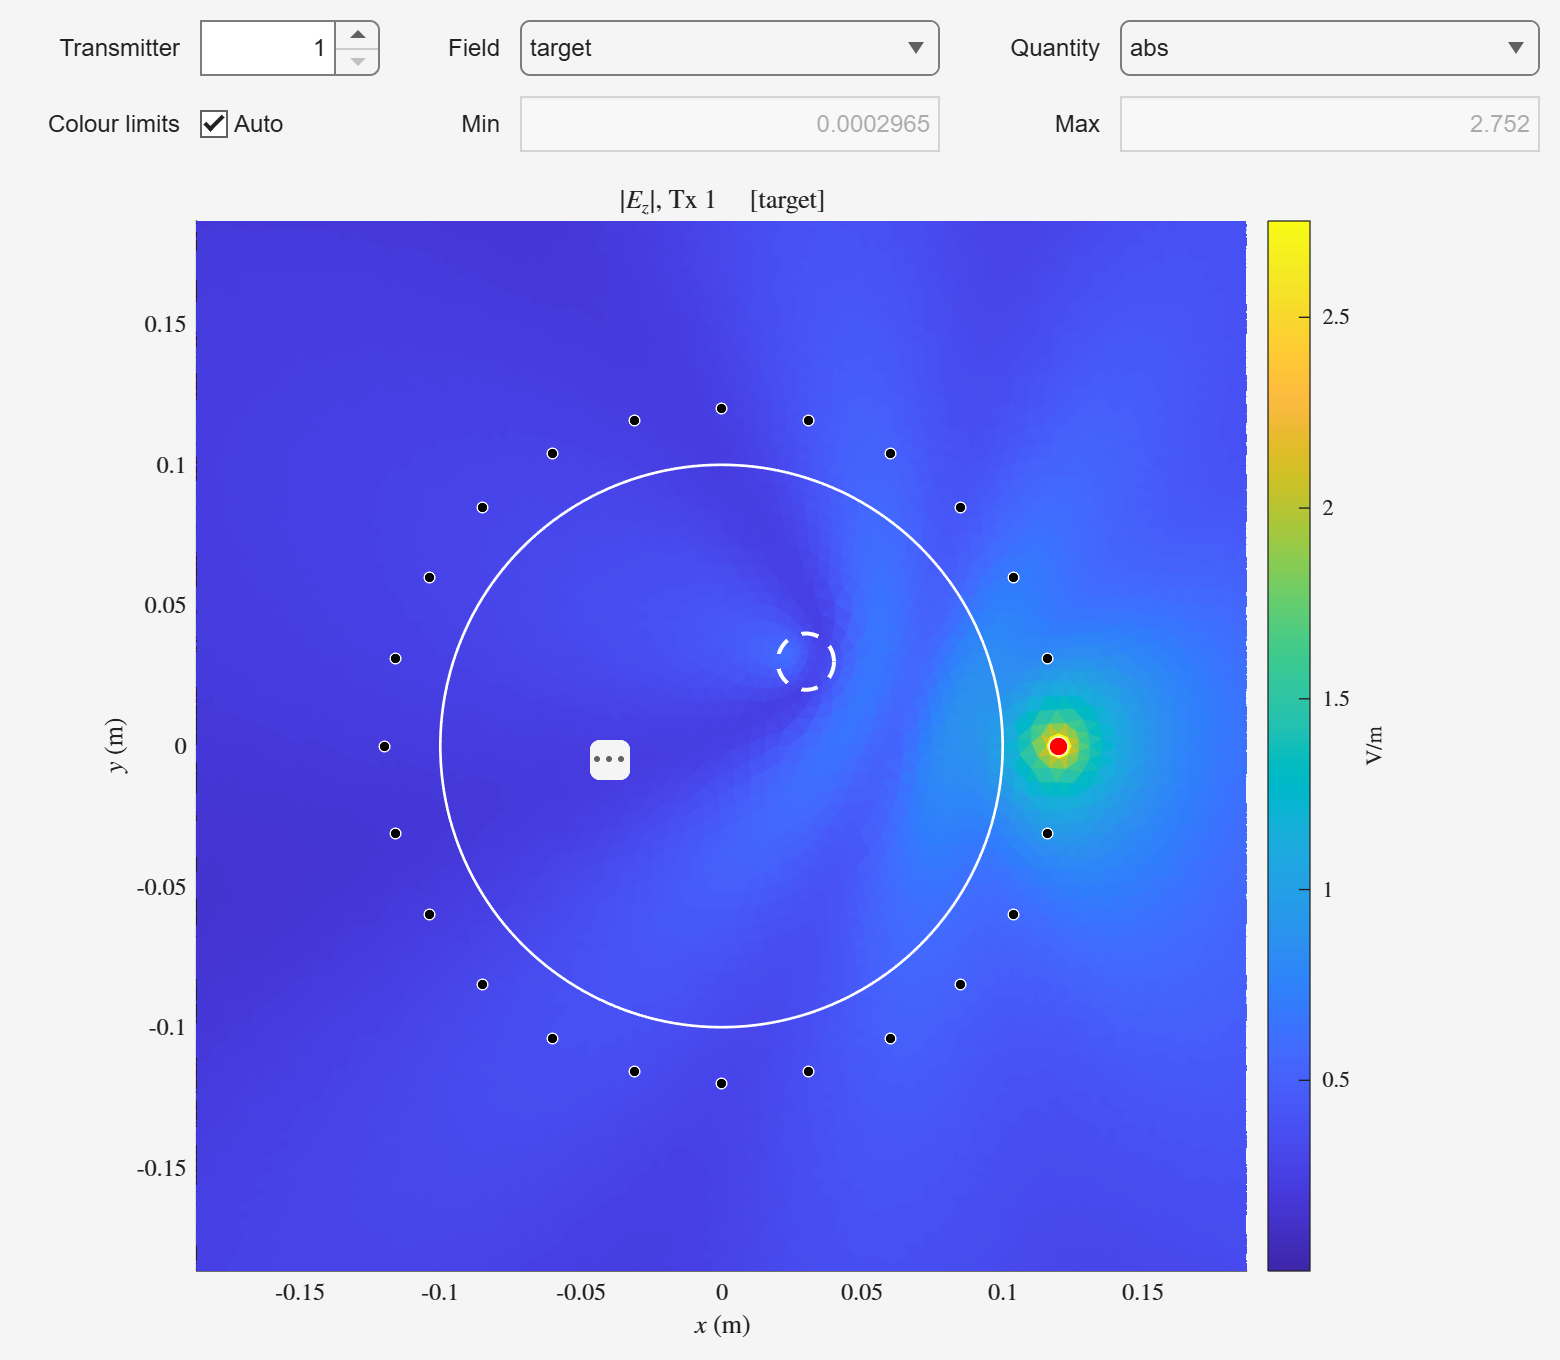

fieldViewer(target, []);